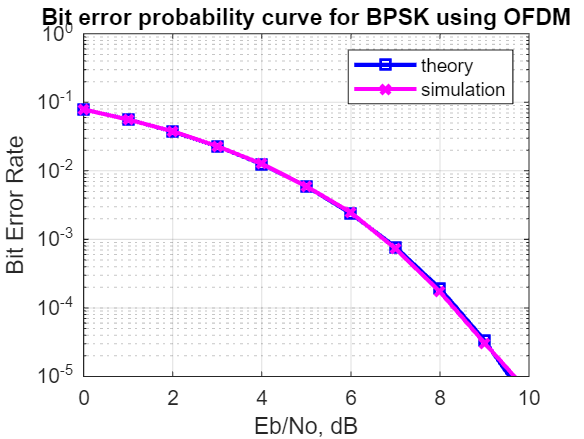

clear all
FFT = 64; % fft size
DSC = 52; % number of data subcarriers
BPS = 52; % number of bits per OFDM symbol (same as the number of subcarriers for BPSK)
S = 10^4; % number of symbols
snr = 0:10; % bit to noise ratio
SNR = snr + 10*log10(DSC/FFT) + 10*log10(64/80); % converting to symbol to noise ratio
for ii = 1:length(snr)
 % Transmitter
 ipBit = rand(1,BPS*S) > 0.5; % random 1's and 0's
 ipMod = 2*ipBit-1; % BPSK modulation 0 --> -1, 1 --> +1
 ipMod = reshape(ipMod,BPS,S).'; % grouping into multiple symbolsa
 % Assigning modulated symbols to subcarriers from [-26 to -1, +1 to +26]
 xF = [zeros(S,6) ipMod(:,[1:BPS/2]) zeros(S,1) ipMod(:,[BPS/2+1:BPS]) zeros(S,5)] ;
 
 % Taking FFT, the term (FFT/sqrt(DSC)) is for normalizing the power of transmit symbol to 1 
 xt = (FFT/sqrt(DSC))*ifft(fftshift(xF.')).';
 % Appending cylic prefix
 xt = [xt(:,[49:64]) xt];
 % Concatenating multiple symbols to form a long vector
 xt = reshape(xt.',1,S*80);
 
 % Gaussian noise of unit variance, 0 mean
 nt = 1/sqrt(2)*[randn(1,S*80) + j*randn(1,S*80)];
 % Adding noise, the term sqrt(80/64) is to account for the wasted energy due to cyclic prefix
 yt = sqrt(80/64)*xt + 10^(-SNR(ii)/20)*nt;
 % Receiver
 yt = reshape(yt.',80,S).'; % formatting the received vector into symbols
 yt = yt(:,[17:80]); % removing cyclic prefix
 % converting to frequency domain
 yF = (sqrt(DSC)/FFT)*fftshift(fft(yt.')).'; 
 yMod = yF(:,[6+[1:BPS/2] 7+[BPS/2+1:BPS] ]); 
 % BPSK demodulation
 % +ve value --> 1, -ve value --> -1
 mh = 2*floor(real(yMod/2)) + 1;
 mh(find(mh>1)) = +1;
 mh(find(mh<-1)) = -1;
 % converting modulated values into bits
 bh = (mh+1)/2;
 bh = reshape(bh.',BPS*S,1).';
% counting the errors
 nErr(ii) = size(find(bh - ipBit),2);
end
simBer = nErr/(S*BPS);
theoryBer = (1/2)*erfc(sqrt(10.^(snr/10)));
close all; figure
semilogy(snr,theoryBer,'bs-','LineWidth',2);
hold on
semilogy(snr,simBer,'mx-','LineWidth',2);
axis([0 10 10^-5 1])
grid on
legend('theory', 'simulation');
xlabel('Eb/No, dB')
ylabel('Bit Error Rate')
title('Bit error probability curve for BPSK using OFDM')